# Diskret Stokastik

## Eksempel 1

clearvars
% Da fx(x) giver det samme for alle værdier, er der lige stor chance for at x er en af de givne tal
% Derfor tæller vi bare hvor mange der er størrere end eller lig med 2.
k = 1/7;
over2 = 4;
over_og_ligmed = 5;
% Pr( x >= 2)
over_og_ligmed * k

ans = 0.7143

% Pr( x > 2)
over2 * k

ans = 0.5714

# Kontinuert Stokastisk

## Eksempel 1

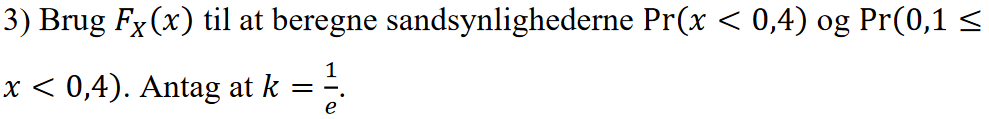

clearvars
% Sandsynligheden for at x er et givet til er Fx(n)
k = 1/exp(1);
syms x
Fx = k*exp(x);
% Pr(x < 0.4)
x = 0.4;
Pr04 = double( subs(Fx) )

Pr04 = 0.5488

% Pr(x < 0.1)
x = 0.1;
Pr01 = double( subs(Fx) )

Pr01 = 0.4066

% Pr(0.1 <= x < 0.4)
Pr0104 = Pr04-Pr01

Pr0104 = 0.1422

## Eksempel 2

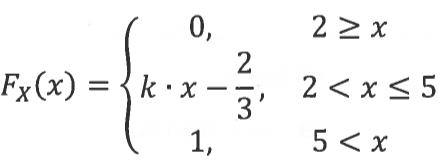

clearvars
% Sandsynligheden for at x er et givet tal = Fx(n)
k = 1/3;
syms x
Fx = (k*x)-2/3;
% Pr(x < 3)
x = 3;
Pr03 = double( subs(Fx) )

Pr03 = 0.3333

% Pr( x >= 3) = 1 - Pr(x < 3)
1 - Pr03

ans = 0.6667

## Eksempel 3

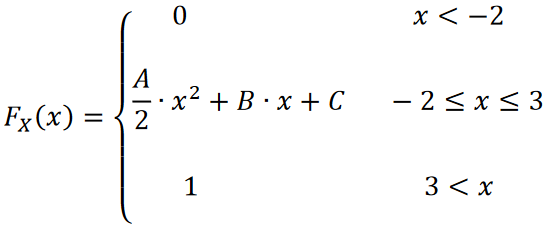

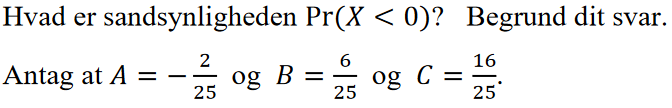

clearvars
syms x
A = -(2/25); B = 6/25; C = 16/25;
% Pr(X < 0) = Fx(0)
Fx = (A/2)*x^2+B*x+C;
x = 0;
double( subs(Fx) )

ans = 0.6400

## Eksempel 4

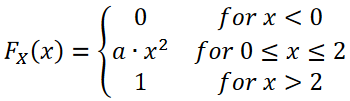

clearvars
% Givet er: a = 1/4
a = 1/4;
syms x
Fx = a*x^2;
% Pr(x < 1)
x = 1;
Pr01 = subs(Fx)

$$Pr01 = \frac{1}{4}$$

% Pr(x < 2)
x = 2;
Pr02 = subs(Fx)

$$Pr02 = 1$$

% Pr(1 <= x <= 2)
Pr02 - Pr01

$$ans = \frac{3}{4}$$